beacon = hlk_beacon_location();
beacon_x = zeros(0);
beacon_y = zeros(0);
labels = cell(0);

for k = 1:1:length(beacon)
    beacon_x(k) = beacon(k).x;
    beacon_y(k) = beacon(k).y;
    name_temp = beacon(k).name;
    labels{k} = strcat('', strrep(name_temp, 'onepos_HLK_', ''));
end

% base map
% ref_point_xy = [beacon_x(1).x, beacon_y(1).y]; % 以ope1信标为参考(0,0)位置
ref_point_xy = [min(beacon_x), min(beacon_y)]; % 以最小x和最小y作为参考位置
beacon_x = reshape(beacon_x, [1, length(beacon_x)]);
beacon_y = reshape(beacon_y, [1, length(beacon_y)]);
beacon_x==min(beacon_x)

ans = 1×10 logical 数组
   0   1   0   0   0   0   0   0   0   0


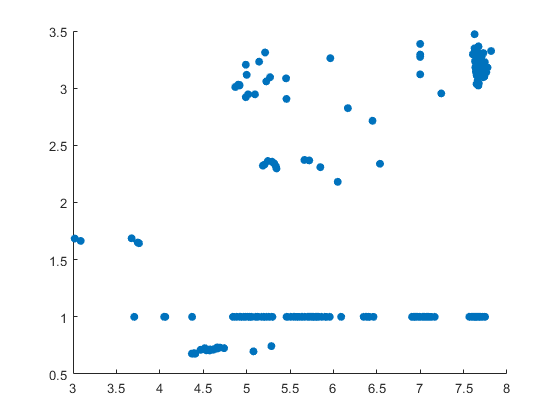

fg = [7.671,3.366;...
7.000,3.387;...
7.631,3.237;...
7.629,3.296;...
7.627,3.310;...
4.372,1.000;...
4.518,0.726;...
3.706,1.000;...
5.470,1.000;...
5.461,1.000;...
6.377,1.000;...
5.798,1.000;...
7.075,1.000;...
5.297,1.000;...
5.259,1.000;...
7.003,1.000;...
6.933,1.000;...
7.099,1.000;...
6.462,1.000;...
7.572,1.000;...
4.741,0.726;...
5.131,1.000;...
5.045,1.000;...
4.991,3.205;...
7.662,1.000;...
7.665,1.000;...
4.392,0.682;...
4.392,0.682;...
4.378,0.680;...
4.369,0.678;...
5.666,2.372;...
6.906,1.000;...
7.698,3.202;...
7.663,3.068;...
7.056,1.000;...
5.205,2.331;...
5.187,2.322;...
5.286,0.744;...
4.534,0.708;...
5.079,0.698;...
4.383,0.679;...
4.370,0.678;...
4.393,0.679;...
6.925,1.000;...
6.940,1.000;...
6.929,1.000;...
6.959,1.000;...
6.951,1.000;...
7.061,1.000;...
7.675,3.042;...
7.670,3.023;...
7.677,3.114;...
4.051,1.000;...
4.055,1.000;...
5.864,1.000;...
5.344,2.298;...
5.245,2.363;...
5.293,2.357;...
5.294,1.000;...
4.693,0.731;...
6.349,1.000;...
5.197,1.000;...
5.233,1.000;...
6.977,1.000;...
7.646,1.000;...
7.634,1.000;...
5.001,3.117;...
5.034,1.000;...
4.885,1.000;...
7.604,1.000;...
7.593,1.000;...
6.406,1.000;...
7.719,3.214;...
4.399,0.680;...
7.710,3.205;...
5.173,1.000;...
5.019,1.000;...
5.204,1.000;...
4.993,1.000;...
5.109,1.000;...
4.917,3.029;...
4.919,3.024;...
4.888,1.000;...
4.971,1.000;...
4.659,0.732;...
4.677,0.730;...
4.682,0.729;...
7.029,1.000;...
7.088,1.000;...
5.803,1.000;...
5.017,2.946;...
5.459,2.906;...
4.991,2.921;...
5.096,2.946;...
7.642,3.141;...
7.707,3.136;...
7.566,1.000;...
5.336,2.318;...
5.318,2.342;...
4.615,0.712;...
4.602,0.713;...
7.650,3.036;...
4.570,0.708;...
4.645,0.722;...
4.063,1.000;...
4.657,0.722;...
4.575,0.706;...
5.906,1.000;...
7.090,1.000;...
7.106,1.000;...
5.921,1.000;...
7.653,1.000;...
7.608,1.000;...
7.615,1.000;...
7.631,1.000;...
7.039,1.000;...
7.635,1.000;...
5.213,3.312;...
5.144,3.232;...
7.000,3.273;...
7.627,3.318;...
7.000,3.294;...
7.722,1.000;...
7.681,1.000;...
7.678,1.000;...
7.660,1.000;...
5.704,1.000;...
5.646,1.000;...
5.673,1.000;...
5.559,1.000;...
5.668,1.000;...
7.707,3.206;...
5.754,1.000;...
5.730,1.000;...
5.744,1.000;...
7.691,3.184;...
5.834,1.000;...
7.747,1.000;...
7.130,1.000;...
7.118,1.000;...
4.396,0.678;...
4.387,0.678;...
4.393,0.677;...
4.395,0.677;...
4.400,0.678;...
4.400,0.678;...
3.675,1.687;...
3.756,1.645;...
4.407,0.681;...
4.399,0.682;...
6.954,1.000;...
7.167,1.000;...
7.729,3.096;...
7.664,3.126;...
7.656,3.168;...
7.652,1.000;...
5.107,1.000;...
7.628,1.000;...
7.630,1.000;...
7.624,1.000;...
7.624,1.000;...
7.689,3.190;...
7.635,3.181;...
7.645,3.205;...
7.640,3.193;...
7.634,3.231;...
7.640,3.170;...
7.655,3.152;...
5.768,1.000;...
4.870,3.010;...
4.904,3.031;...
7.660,1.000;...
7.666,1.000;...
7.662,1.000;...
7.675,1.000;...
7.676,1.000;...
7.655,1.000;...
4.403,0.680;...
7.702,1.000;...
7.661,3.281;...
7.659,3.281;...
7.647,1.000;...
7.627,1.000;...
7.000,3.121;...
7.590,1.000;...
7.650,3.112;...
7.727,3.307;...
5.965,3.262;...
5.782,1.000;...
5.774,1.000;...
5.511,1.000;...
5.609,1.000;...
5.958,1.000;...
3.089,1.664;...
7.597,1.000;...
7.595,1.000;...
7.597,1.000;...
6.388,1.000;...
6.414,1.000;...
4.394,0.682;...
4.389,0.679;...
4.471,0.712;...
5.724,1.000;...
4.569,0.709;...
4.628,0.717;...
4.628,0.719;...
7.594,1.000;...
7.596,1.000;...
4.939,1.000;...
4.409,0.678;...
4.409,0.678;...
7.739,3.102;...
7.738,3.162;...
7.761,3.139;...
7.669,3.189;...
7.661,3.184;...
5.636,1.000;...
7.628,1.000;...
7.630,1.000;...
4.399,0.678;...
7.677,3.218;...
7.055,1.000;...
7.711,3.284;...
7.745,3.227;...
7.776,3.180;...
7.243,2.954;...
6.537,2.339;...
5.722,2.368;...
5.850,2.309;...
7.570,1.000;...
5.455,3.086;...
4.843,1.000;...
4.860,1.000;...
5.060,1.000;...
4.969,1.000;...
5.545,1.000;...
3.020,1.685;...
5.563,1.000;...
5.715,1.000;...
5.715,1.000;...
7.676,1.000;...
7.667,3.246;...
7.685,3.283;...
4.402,0.680;...
4.398,0.680;...
7.657,3.346;...
7.626,3.348;...
7.671,3.365;...
7.647,3.351;...
7.607,3.296;...
3.746,1.650;...
3.760,1.644;...
4.404,0.678;...
5.227,3.059;...
5.270,3.096;...
5.231,1.000;...
5.810,1.000;...
5.819,1.000;...
4.669,0.725;...
4.544,0.713;...
7.817,3.325;...
6.167,2.825;...
6.451,2.715;...
5.778,1.000;...
6.090,1.000;...
5.585,1.000;...
4.922,1.000;...
5.042,1.000;...
7.690,1.000;...
7.697,1.000;...
4.406,0.677;...
6.050,2.181;...
6.998,1.000;...
7.616,1.000;...
7.608,1.000;...
7.000,3.275;...
7.627,3.472;...
4.574,0.715;...
5.752,1.000];
figure()
scatter(fg(:,1),fg(:,2),'filled')